% get all neams of exp (fields in IC_Galvo

exps_all = fieldnames(IC_Galvo)

exps_all = 6×1 cell array
    {'E12_03_20_1683'}
    {'E12_03_20_1722'}
    {'E12_03_20_1724'}
    {'E12_03_20_1789'}
    {'E16_03_20_1727'}
    {'E16_03_20_1779'}


conditions = fieldnames(IC_Galvo.E12_03_20_1683.touch_times)

conditions = 3×1 cell array
    {'Aluminum'}
    {'Muted'   }
    {'noObject'}


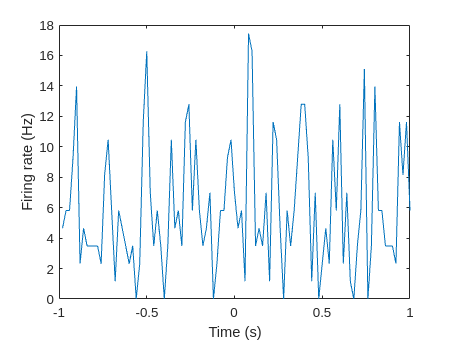

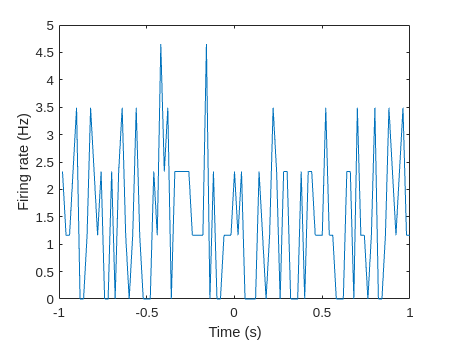

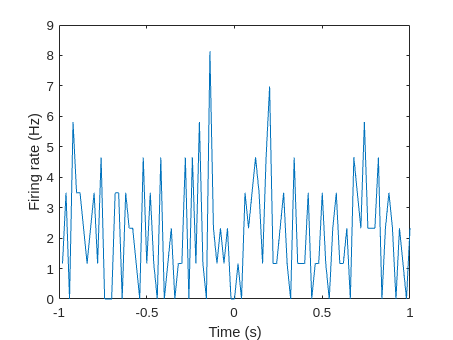

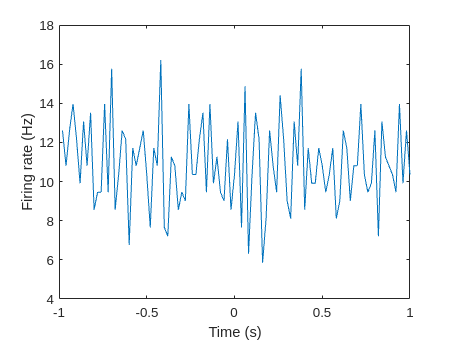

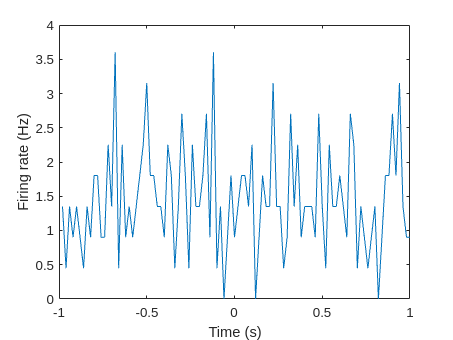

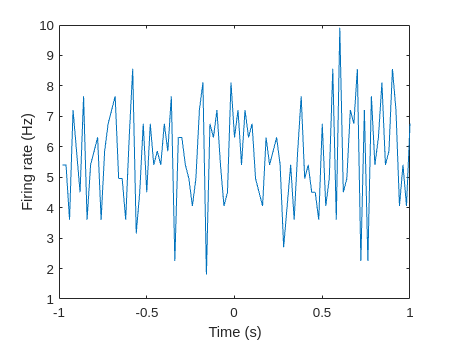

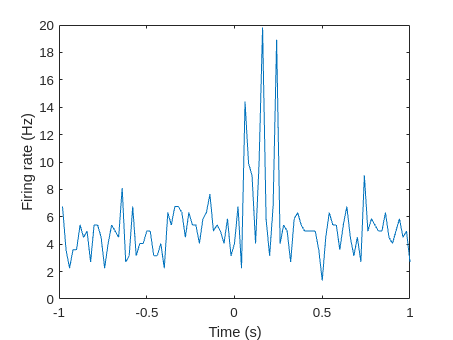

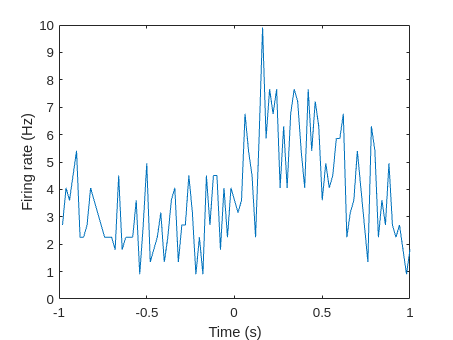

% Run createRaster and PSTh on all
% aluminum rasters
Aluminum = getAllExpPSTH('Aluminum',IC_Galvo,20,2);

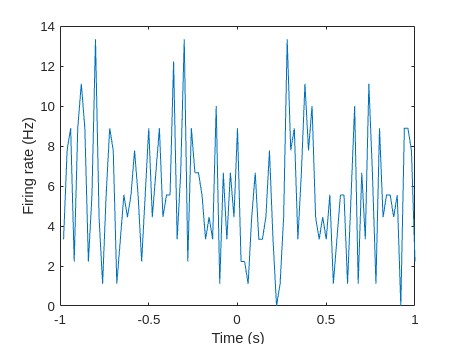

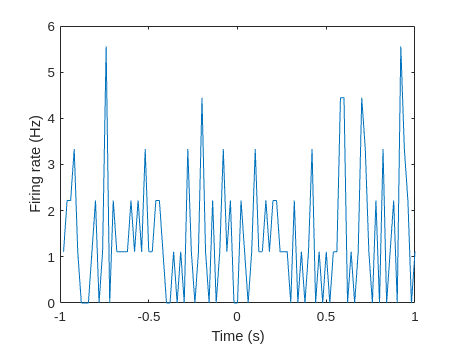

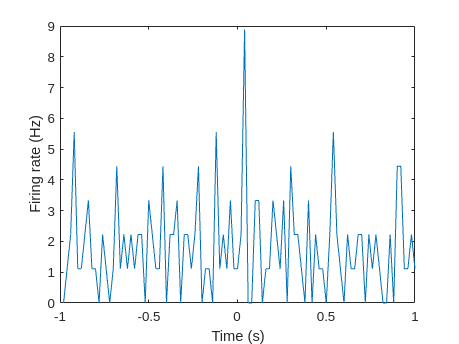

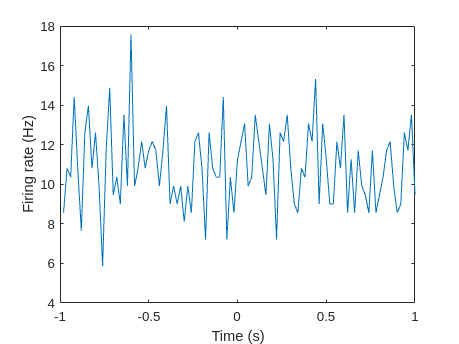

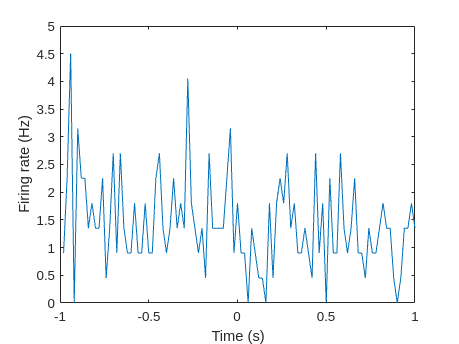

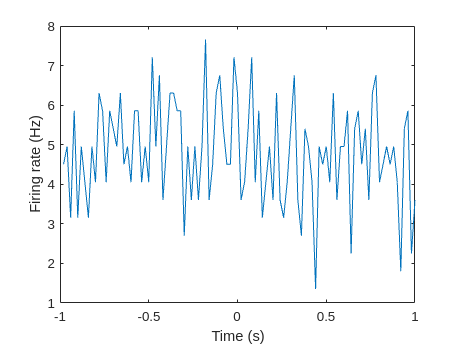

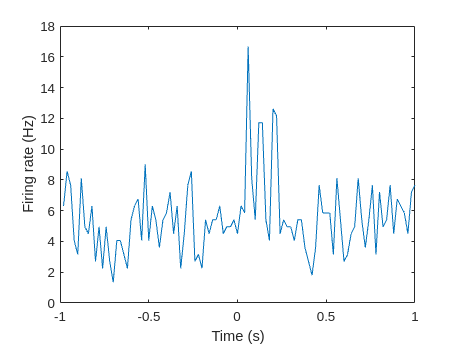

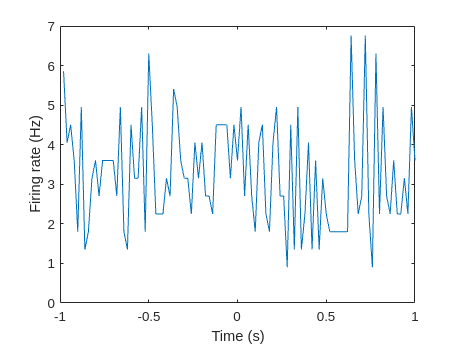

Muted = getAllExpPSTH('Muted',IC_Galvo,20,2);

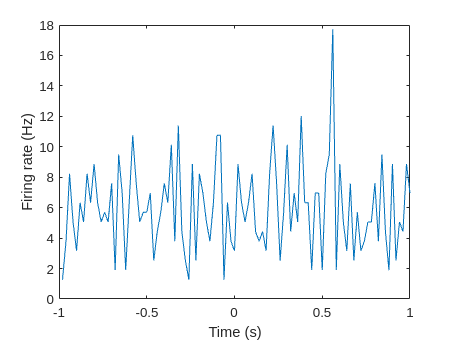

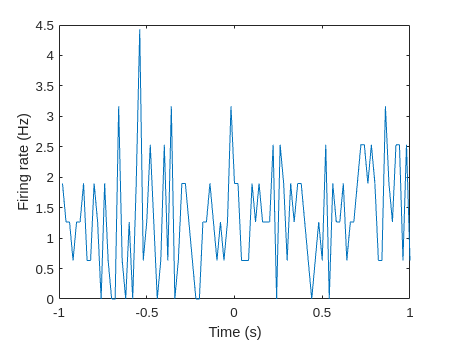

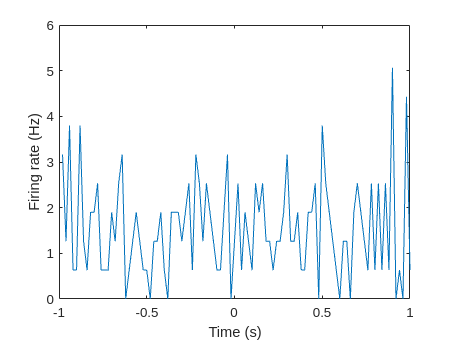

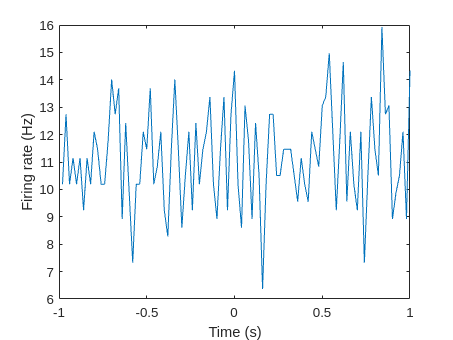

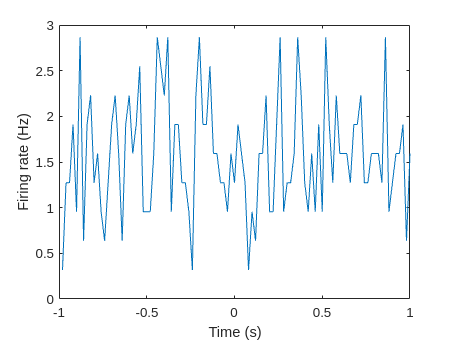

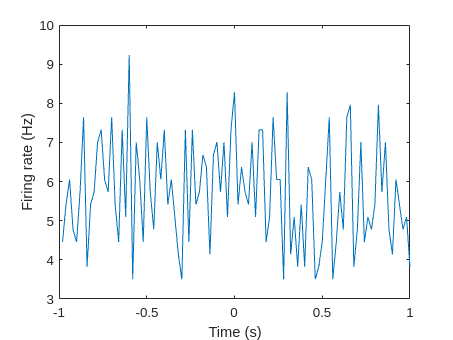

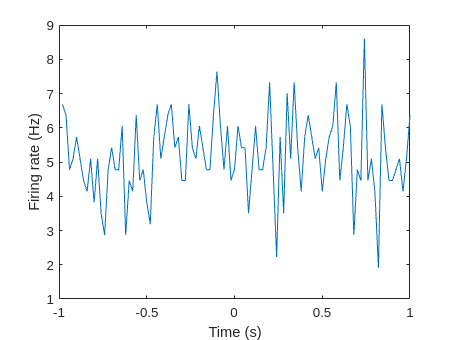

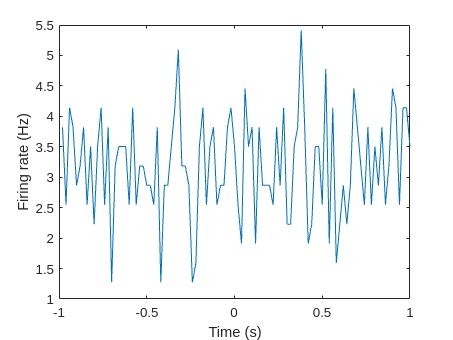

non = getAllExpPSTH('noObject',IC_Galvo,20,2);

xVal = -4.48:0.02:4.5

xVal =    -4.4800   -4.4600   -4.4400   -4.4200   -4.4000   -4.3800   -4.3600   -4.3400   -4.3200   -4.3000   -4.2800   -4.2600   -4.2400   -4.2200   -4.2000   -4.1800   -4.1600   -4.1400   -4.1200   -4.1000   -4.0800   -4.0600   -4.0400   -4.0200   -4.0000   -3.9800   -3.9600   -3.9400   -3.9200   -3.9000   -3.8800   -3.8600   -3.8400   -3.8200   -3.8000   -3.7800   -3.7600   -3.7400   -3.7200   -3.7000   -3.6800   -3.6600   -3.6400   -3.6200   -3.6000   -3.5800   -3.5600   -3.5400   -3.5200   -3.5000


Aluminum.normalized = Aluminum.PSTH-mean(Aluminum.PSTH(:,1:220),2);
Muted.normalized = Muted.PSTH-mean(Muted.PSTH(:,1:220),2);
non.normalized = non.PSTH-mean(non.PSTH(:,1:220),2);

%iterae over all EXP in IC_Galvo
Aluminum.normalized = normalize(Aluminum.normalized,2,'zscore');
Muted.normalized = normalize(Muted.normalized,2,'zscore');
non.normalized = normalize(non.normalized,2,'zscore');



[m,n] = max(alumNorm');
[i,c] = sort(n,'descend');

alumSorted = alumNorm(c,:);
mutSorted = mutNorm(c,:);
nonSorted = nonNorm(c,:);




Aluminum.normalized(isnan(Aluminum.normalized)) = 0;
Muted.normalized(isnan(Muted.normalized)) = 0;
non.normalized(isnan(non.normalized)) = 0;


Aluminum.mean = mean(Aluminum.normalized);
Muted.mean = mean(Muted.normalized);
non.mean = mean(non.normalized);


Aluminum.STD = std(Aluminum.normalized);
Muted.STD = std(Muted.normalized);
non.STD = std(non.normalized);


Aluminum.ci_lower = Aluminum.mean - 1.96 * Aluminum.STD / sqrt(length(FR));
Aluminum.ci_upper = Aluminum.mean + 1.96 * Aluminum.STD / sqrt(length(FR));

Muted.ci_lower = Muted.mean - 1.96 * Muted.STD / sqrt(length(FR));
Muted.ci_upper = Muted.mean + 1.96 * Muted.STD / sqrt(length(FR));

non.ci_lower = non.mean - 1.96 * non.STD / sqrt(length(FR));
non.ci_upper = non.mean + 1.96 * non.STD / sqrt(length(FR));

figure; 
hold on;
plot(xVal,Aluminum.mean,'Color',colorBen.aluminum,'LineWidth',2)
x = [xVal, fliplr(xVal)]; y = [Aluminum.ci_lower, fliplr(Aluminum.ci_upper)];
fill(x, y, colorBen.aluminum, 'LineStyle', 'none', 'FaceAlpha', 0.1);
plot(xVal,Muted.mean,'Color',colorBen.muted,'LineWidth',2)
x = [xVal, fliplr(xVal)]; y = [Muted.ci_lower, fliplr(Muted.ci_upper)];
fill(x, y, colorBen.muted, 'LineStyle', 'none', 'FaceAlpha', 0.1);
plot(xVal,non.mean,'Color',colorBen.non,'LineWidth',2)
x = [xVal, fliplr(xVal)]; y = [non.ci_lower, fliplr(non.ci_upper)];
fill(x, y, colorBen.non, 'LineStyle', 'none', 'FaceAlpha', 0.1);

xlim([-1 1])
title('Response of units to onset of whisker movement')
xlabel('time(sec)')
ylabel('Nomralized change in FR(z-score)')
legend({'Aluminum','','Attenuated foil','','No Object'})

xline(0,'--')

xlim([-1 1])
225:235

forFridman = [mean(Aluminum.PSTH(:,225:238),2),mean(Muted.PSTH(:,225:238),2),mean(non.PSTH(:,225:238),2)]

[p, tbl, stats] = friedman(forFridman);

multiCompFriemand = multcompare(stats)

figure; plot(IC_Galvo.E12_03_20_1683.meanSound.Aluminum.whisk  )

%get all FR
FR = [];
for ex = 1:6
    tempFR = getFR(IC_Galvo.(exps_all{ex}));
    FR = [FR;tempFR];
end

h = getFR(IC_Galvo.E12_03_20_1683)

tempFR = getFR(IC_Galvo.(exps_all{ex}));


galvoFig(xVal, Aluminum, 11, Muted, non, colorBen,galvoOnce);


figure; 
subplot(4,3,[1,9])
imagesc(xVal,1:size(alumSorted,1),alumSorted)
colorbar('east','Position',[0.928829915560916,0.342375667899712,0.02573381584238,0.569256062474311])
ylabel('IC units')
clim([-2.5,6])
title('IC unit response to motorized whiskers movement against aluminum')
subplot(4,3,[10 12])
plot(xVal,mean(alumSorted(~isnan(alumSorted(:,1)),:)));
title('mean response')
ylabel('normalized SDF (z-score)')
xlabel('time(s)')
ylim([-0.5,2.5])
figure; 
subplot(4,3,[1,9])
imagesc(xVal,1:size(mutSorted,1),mutSorted)
ylabel('IC units')
title('IC unit response to motorized whiskers movement against attenuated aluminum')
colorbar('east','Position',[0.928829915560916,0.342375667899712,0.02573381584238,0.569256062474311])
clim([-2.5,6])
subplot(4,3,[10 12])
plot(xVal,mean(mutSorted(~isnan(mutSorted(:,1)),:)));
ylim([-0.5,2.5])
ylabel('normalized SDF (z-score)')
xlabel('time(s)')
title('mean response')
figure; 
subplot(4,3,[1,9])
imagesc(xVal,1:size(nonSorted,1),nonSorted)
ylabel('IC units')
title('IC unit response to motorized whiskers movement')
colorbar('east','Position',[0.928829915560916,0.342375667899712,0.02573381584238,0.569256062474311])
clim([-2.5,6])
subplot(4,3,[10 12])
plot(xVal,mean(nonSorted(~isnan(nonSorted(:,1)),:)));
ylim([-0.5,2.5])
ylabel('normalized SDF (z-score)')
xlabel('time(s)')
title('mean response')


    % plot hitmap of all IC_Galvo exps in all three conditions



% plot mean psth of all plus STE lines dashed



% plot mean normalized to baseline response of time bin after galvo +
% statistics




function [galvoPSTH,galvoRasters,galvoSDF] = getGalvoPsth(condition,exp_struct,time_window,timeBin)
galvoTimes = exp_struct.touch_times.(condition)(:,30000);
goodUnits = getUnits(exp_struct.clusterSpikes.good.times);
muaUnits = getUnits(exp_struct.clusterSpikes.mua.times);
allUnits = [goodUnits';muaUnits'];
galvoPSTH = zeros(length(allUnits),time_window/(timeBin/1000));
galvoSDF = zeros(length(allUnits),time_window*1000);
galvoRasters = cell(length(allUnits),1);
for unit = 1:length(allUnits)
    rasterUnit = createRaster(galvoTimes,allUnits{unit},time_window);
    tempPSTH = psth(rasterUnit,timeBin);
    %tempSDF = getSDF(mean(rasterUnit));
    galvoPSTH(unit,:) = tempPSTH;
    galvoRasters{unit} = rasterUnit;
%    galvoSDF(unit,:) = tempSDF;
end
end

function [unit,FR] = getUnits(allUnits)
if ~isempty(allUnits)
    expLength = max(allUnits(:,length(allUnits)))/30000;
    k = 1;
    for i = 1:size(allUnits,1)
        unitTemp =nonzeros(allUnits(i,:));
        if length(unitTemp) >= (0.1*expLength)
            unit{k} = unitTemp';
            FR(k) = length(unitTemp)/expLength;
            k =k + 1;
        end
    end
else
    unit = {};
end

end
function condition_raster = getAllExpPSTH(condition,mainStructure,timeBin,time_window)
ICG = mainStructure;
exps_all = fieldnames(mainStructure);
condition_raster.rasters = {};
condition_raster.PSTH = [];
condition_raster.SDF = [];
for exp = 1:length(exps_all)
    [galvoPSTH,galvoRasters,galvoSDF] = getGalvoPsth(condition,ICG.(exps_all{exp}),time_window,timeBin);
    condition_raster.rasters = [condition_raster.rasters;galvoRasters];
    condition_raster.PSTH = [condition_raster.PSTH;galvoPSTH];
    
    %condition_raster.SDF = [condition_raster.SDF;galvoSDF];
end

end

function expFR = getFR(galvoStruct)
    [~,expFRgood] = getUnits(galvoStruct.clusterSpikes.good.times);
    try
        [~,expFRmua] = getUnits(galvoStruct.clusterSpikes.mua.times);
        expFR = [expFRgood,expFRmua];
    catch
        expFR = expFRgood;
    end
    expFR = expFR';

end
